# **Matlab案例代码解析**

## 4. 图像信号处理案例

### 4.1 滤波

#### 4.1.2 二维非局部均值滤波

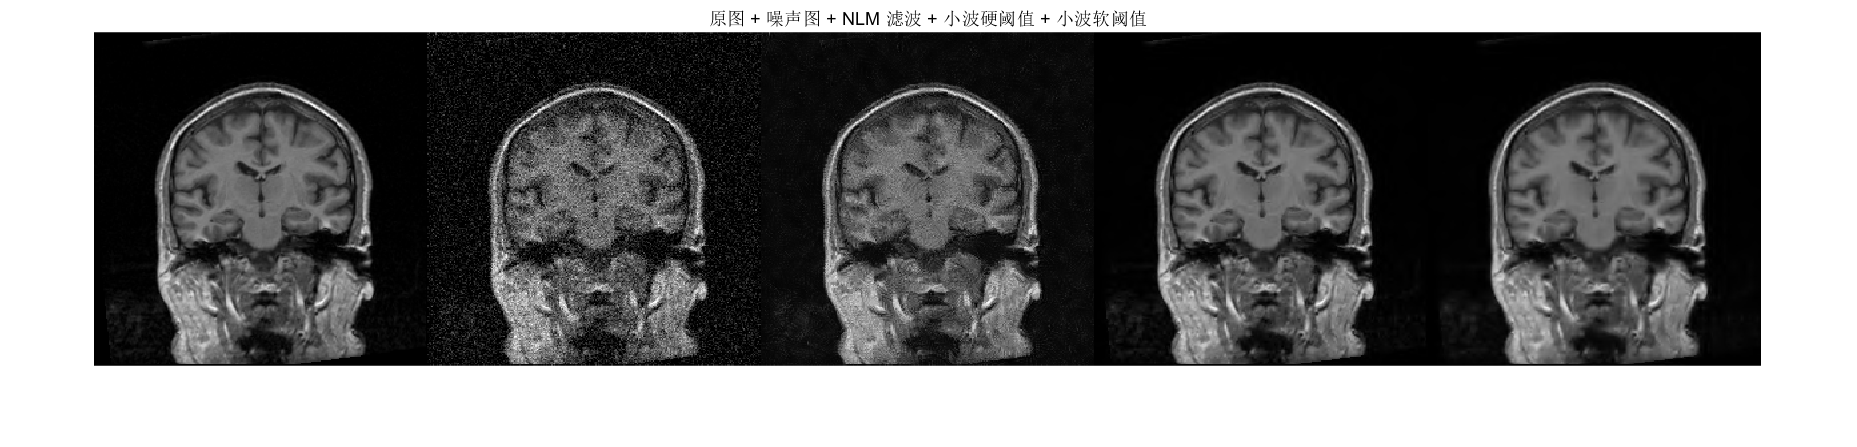

clear;clc;
im = imread('brain.bmp');
if size(im, 3) > 1
    im = rgb2gray(im);
end
rng('default')
im0 = imnoise(im, 'gaussian', 0, 1e-2); % 原图像 + 白噪声
im1 = Nlm2D(im0, 5, 4, 0.15);
% matlab 小波
wname = 'db3'; % 小波类型    
n = 3;         % 分解层数    
sorh1 = 'h';   % 硬阈值    
sorh2 = 's';   % 软阈值    
% 对图像进行小波分解    
[c, l] = wavedec2(im, n, wname);  
% 求取阈值  
N = numel(im);  
[chd1, cvd1, cdd1] = detcoef2('all',c,l,1);   
cvd1 = cvd1(:)';  
sigma = median(abs(cvd1)) / 0.6745; % 提取细节系数求中值并除以0.6745  
thr = sigma*sqrt(2*log(N));   
% 对小波系数全局阈值处理    
cxch = c;   % 保留近似系数    
cxcs = c;   % 保留近似系数    
justdet = prod(l(1, :)) + 1:length(c);  % 截取细节系数（不处理近似系数）    
% 阈值处理细节系数    
cxch(justdet) = wthresh(cxch(justdet), sorh1, thr);  % 硬阈值去噪    
cxcs(justdet) = wthresh(cxcs(justdet), sorh2, thr);  % 软阈值去噪    
% 小波重建    
xch = waverec2(cxch, l, wname);    
xcs = waverec2(cxcs, l, wname);
xch = uint8(xch);
xcs = uint8(xcs);
montage([im, im0, im1, xch, xcs]);
title('原图 + 噪声图 + NLM 滤波 + 小波硬阈值 + 小波软阈值');